## Perlin NoiseによるPotentialの生成

ポテンシャル$\Psi(\mathbf{p})$は以下の式で与えられる．    

    
$$\Psi(\mathbf{p}) = N_{perlin}(\mathbf{p})$$


ただしPerlin Noiseの設定は以下の通り．

seed        =  25;
size        = 318;
n_tiles     =    1;
n_octaves   =  13;
persistence =0.315;

rng(seed);

Psi       = zeros(size);
idxs    = 1:n_octaves;
max_amp = sum(persistence.^(idxs-1));

for i = idxs
    Psi = Psi + ...
        imresize(rand(n_tiles*i), ...
                [size size],"cubic")*...
        persistence^(i-1)/...
        max_amp;
end

## 勾配の計算

ポテンシャルの勾配$\nabla \Psi$を求める．勾配は以下の式で与えられる．


$$\nabla \Psi = \left(\frac{d\Psi}{dx}, \frac{d\Psi}{dy}\right)$$


[dNdx,dNdy] = gradient(Psi);

## 速度のベクトル場を計算

$\nabla \Psi$と直交する速度ベクトル$\mathbf{v}$を求める．

vx =  dNdy;
vy = -dNdx;

## 可視化

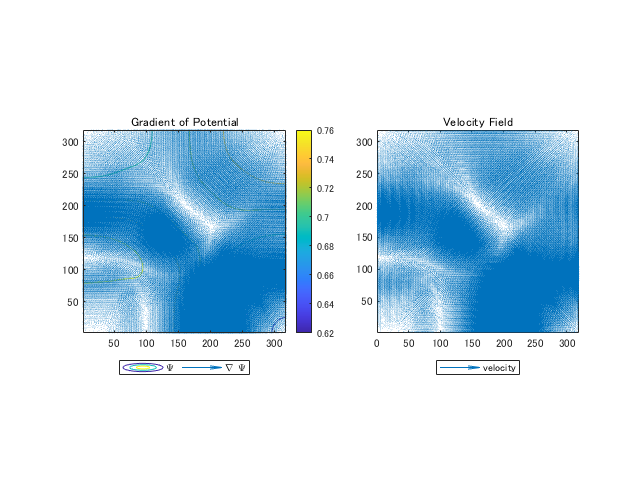

fig = figure("Position",[0,0,640,480]);
tiledlayout(1,2);

nexttile;
contour(Psi);
hold on
quiver(dNdx,dNdy);
xlim([-inf inf]);
ylim([-inf inf]);
pbaspect([1 1 1 ]);
title("Gradient of Potential");
legend("\Psi","\nabla \Psi", ...
       "Location","southoutside", ...
       "Orientation","horizontal");
colorbar
hold off

nexttile;
quiver(vx,vy);
xlim([-inf inf]);
ylim([-inf inf]);
pbaspect([1 1 1 ]);
title("Velocity Field");
legend("velocity", ...
       "Location","southoutside", ...
       "Orientation","horizontal");
hold off
copygraphics(gcf,"Resolution",300, ...
            "ContentType","image");

## Reference

[https://web.archive.org/web/20080724063449/http://freespace.virgin.net/hugo.elias/models/m_perlin.htm](https://web.archive.org/web/20080724063449/http://freespace.virgin.net/hugo.elias/models/m_perlin.htm)